Ntrain = 400;
Ntest = 100;

Nfold = 10;
err_train = zeros(Nfold,1);
err_test = zeros(Nfold,1);

for i = 1:Nfold
    [err_train(i), err_test(i)] = NARMA2(Ntrain, Ntest);
end

mean(err_train)

ans = 0.0019

mean(err_test)

ans = 0.0022

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tic
K = 8;
C = 8;
Ntrain = 400;
Ntest = 100;
flag = -1*ones(K*(K-1)/2,1);
%flag(12) = 0;

Nfold = 1;
err_train = zeros(Nfold,1);
err_test = zeros(Nfold,1);
for i = 1:Nfold
    [err_train(i), err_test(i)] = NARMA2_KxC(Ntrain, Ntest,K,C,flag);
end
toc

Elapsed time is 45.353434 seconds.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tic
K = 8;
C = 8;
Ntrain = 400;
Ntest = 100;
M = 4;
Mn = K*(K-1)/(2*M);
liq_pop = 1:K*(K-1)/2;
liq_pop = liq_pop(randperm(length(liq_pop)));
flag = zeros(K*(K-1)/2,1);
pmax = 0.08:-0.05:0.1-0.05*(Mn-1);
%pmax = 0.08
Nfold = 10;
err_train = zeros(Nfold,Mn);
err_test = zeros(Nfold,Mn);
for j = 1:Mn
    flag(liq_pop(M*(j-1)+1:M*j)) = -1;
    for i = 1:Nfold
        [err_train(i,j), err_test(i,j)] = NARMA2_KxC(Ntrain, Ntest,K,C,flag,pmax(j));
    end
end
toc

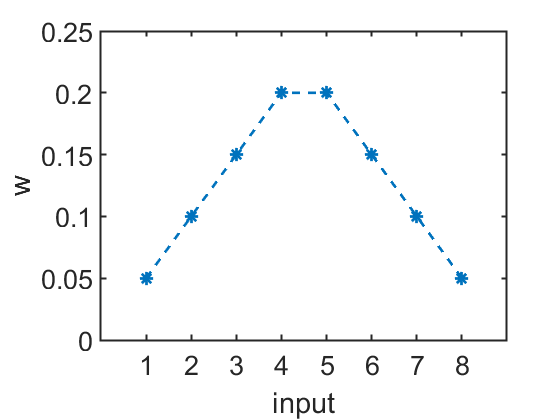

K = 8;
C = 8;
Ntrain = 400;
Ntest = 100;
M = 4;
Mn = K*(K-1)/(2*M);

inp_w = zeros(K,1);
inp_w(1:K/2) = 4*(1:1:K/2)/(K*(K+2));
inp_w(K/2+1:K) = 4*(K/2:-1:1)/(K*(K+2));

figure; hold on;
plot(inp_w,'LineWidth',2,"Marker","*",'MarkerSize',10,'LineStyle',"--")
xlabel('input')
ylabel('w')
ylim([0 0.25])
xlim([0 9])
xticks(1:8)
set(gca,'FontSize',20)
set(gca,'linewidth',1.5)
set(gca,'box',1)